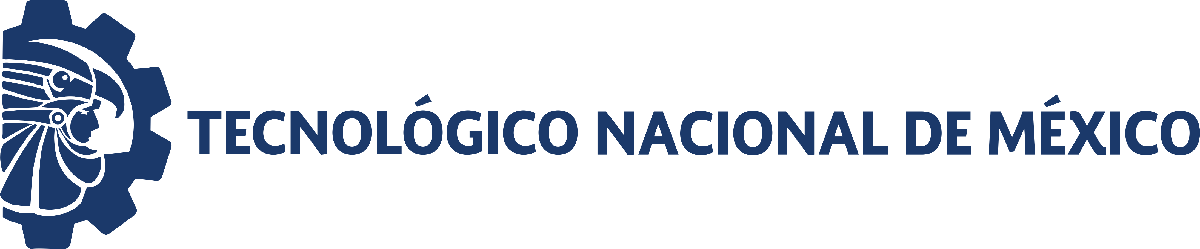                                 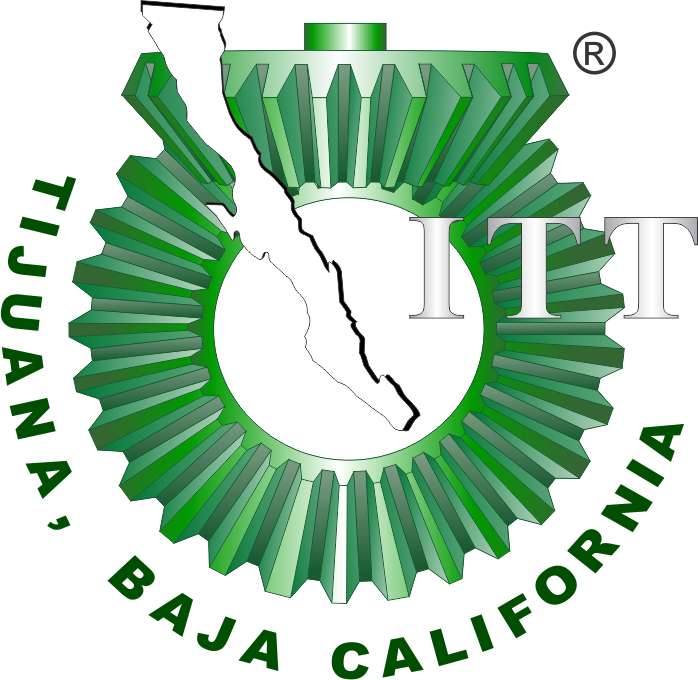

# PROYECTO FINAL: SISTEMA TEGUMENTARIO

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

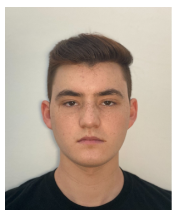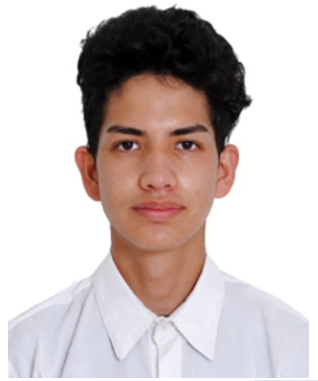

Nombre de los alumnos y número de control :

**Campoy Alegria Marco Antonio, 21212145**

**Sanchez Perez Keybin Daniel, 23210721**

Correos institucionales: 

**l21212145@tectijuana.edu.mx**

**l23210721@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'Sistema';
open_system(file);
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
x = sim(file,parameters);

## Respuesta del sistema

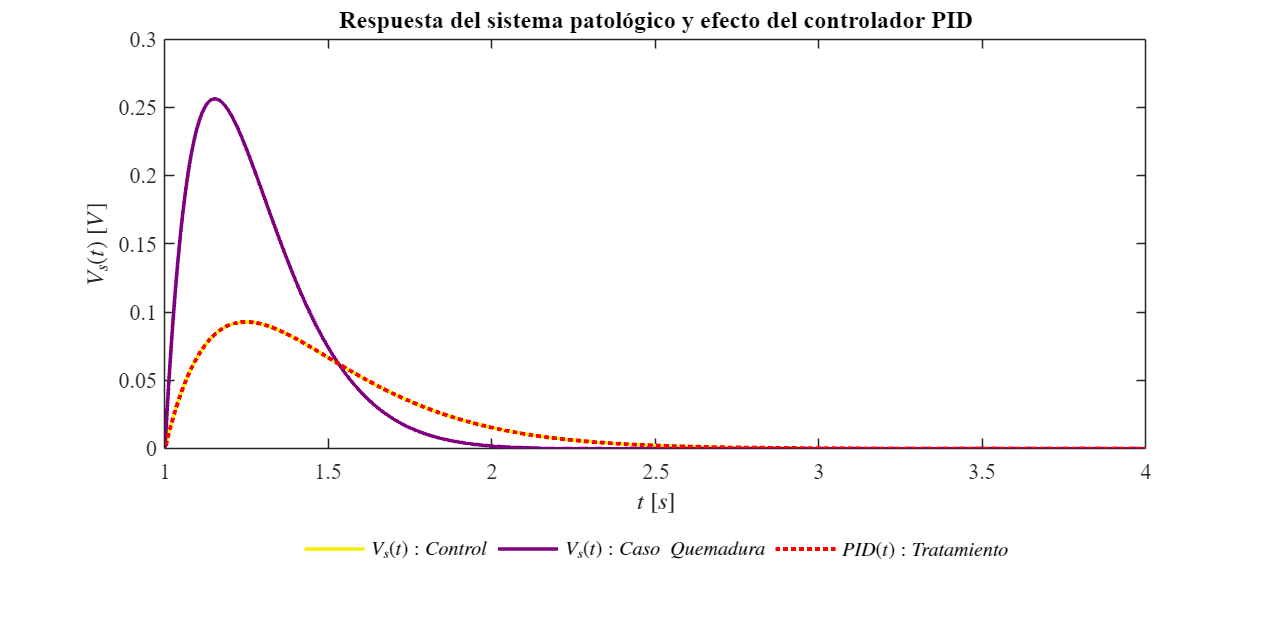

plotsignals(x.t, x.Ve, x.Control, x.Caso, x.PID)

## Función respuesta del sistema

function plotsignals(t, Ve, Control, Caso, PID)

    %% Asegurar vectores columna
    t = t(:);
    Control = Control(:);
    Caso = Caso(:);
    PID = PID(:);

    %% Tamaño de la figura
    fig = figure();
    set(fig, 'Color', 'w', 'Units', 'centimeters', 'Position', [2, 2, 24, 12]);

    %% Colores
    colorControl = [0.95, 0.95, 0.00];   % Amarillo
    colorCaso    = [0.50, 0.00, 0.50];   % Morado
    colorPID     = [1.00, 0.00, 0.00];   % Rojo

    %% Gráfica: Control, Caso y PID
    box on; hold on;

    P = plot(t, Control, '-', ...
             t, Caso, '-', ...
             t, PID, ':', ...
             'LineWidth', 1.6);

    set(P(1), 'Color', colorControl, 'LineWidth', 1.8)
    set(P(2), 'Color', colorCaso, 'LineWidth', 1.8)
    set(P(3), 'Color', colorPID, 'LineWidth', 2.0)

    ylabel('$V_s(t)$ $[V]$', 'Interpreter', 'Latex', 'FontSize', 12)
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 12)

    xlim([1 4])
    xticks(1:0.5:4)

    ylim([0 0.30])
    yticks(0:0.05:0.30)

    title('Respuesta del sistema patológico y efecto del controlador PID', ...
          'FontSize', 13, 'FontWeight', 'bold')

    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11)

    L = legend('$V_s(t): Control$', ...
               '$V_s(t): Caso\ Quemadura$', ...
               '$PID(t): Tratamiento$');

    set(L, 'Interpreter', 'Latex', ...
        'FontSize', 10, ...
        'Location', 'SouthOutside', ...
        'Orientation', 'Horizontal', ...
        'Box', 'Off');

    exportgraphics(gcf, 'tegumentariomath.pdf', 'ContentType', 'vector')

end